MA-1006

Grupo: 02

Estudiante: Josef Ruzicka González

Carnet: B87095

# Tarea #1

**Instrucciones:**				

- Todo debe trabajarlo en este .mlx

- Si realiza procesos a mano puede agregar las imágenes insertándolas.

- Recuerde que puede consultar con el docente si tiene dudas. 

- Para las M-funciones procure comentar para indicar que es lo que se hace en cada paso. 

- El total de puntos es de 100. 

## Ejercicios

1) **(40 puntos) **Dado un triángulo de vértices $X, Y, Z$, y un punto $P$ del plano, se verifica que: el punto $P$pertenece al triángulo $XYZ$ si y sólo si $A = A1 + A2 + A3,$ donde 

A = área del triángulo XYZ, 

A1 = área del triángulo XYP, 

A2 = área del triángulo YZP,  

A3 = área del triángulo ZXP.

Escribir una M-función, $\texttt{function [bool] = PuntoEnTriangulo(X, Y, Z, P)}$

que devuelva $\texttt{bool = true}$ si el punto P pertenece al triangulo XY Z y $\texttt{bool = false}$ si no.

Indicación: La función de MATLAB $\texttt{polyarea}$ sirve para calcular el área de un polígono plano. 

De la documentación de Matlab obtenemos la siguiente información

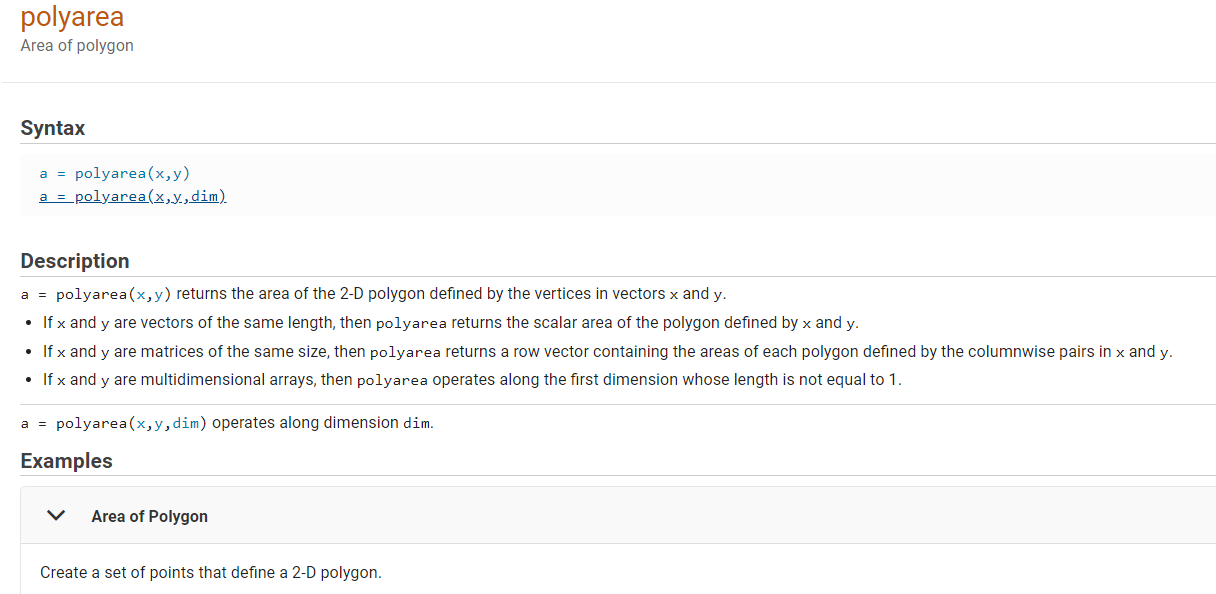

Asumimos X como el vector con las coordenadas en el eje x de cada punto y Y como el vector con las coordenadas en el eje y de cada punto

% Escriba su codigo ejecutable aca...

% Creamos puntos con coordenadas 'x' y 'y'
X = [5 0];
Y = [3 4];
Z = [2 2];
P1 = [3 4];
P2 = [6 6];

% Creamos un caso de prueba para true y uno para false
bool1 = PuntoEnTriangulo(X, Y, Z, P1)

areas =      4     0     0     4     0


bool1 = logical
   1


bool2 = PuntoEnTriangulo(X, Y, Z, P2)

areas =      4     8     0    10     2


bool2 = logical
   0


2) **(60 puntos)** Vamos a calcular las soluciones de la ecuacion

#### $\sin\left(\frac{x}{2} \right) \cdot \cos\left( \sqrt{x}\right) = \frac{1}{5} $ en el intervalo $[0, \, \pi]$ 

a) Utilize la funcion $\texttt{fzero}$ de MATLAB para mostrar que existen soluciones en los intervalos $[0.4, 0.7]$ y $[1.5, 2]$. 		

% Escriba su codigo ejecutable aca...
% Declaramos la funcion y los rangos.

% Convertimos la equacion en homogenear, no estoy seguro si ese es el
% termino correcto
f = @(x) (sin(x/2))*(cos(sqrt(x))) -1/5;
x0 = [0.4, 0.7];
x00 = [1.5, 2];

% Calculamos
fzero(f, x0)

ans = 0.5490

fzero(f, x00)

ans = 1.6904

b) Determine una funcion $f$ en los intervalos del inciso a), y realice una grafica con MATLAB en la que se visualicen las raices encontradas en a). 

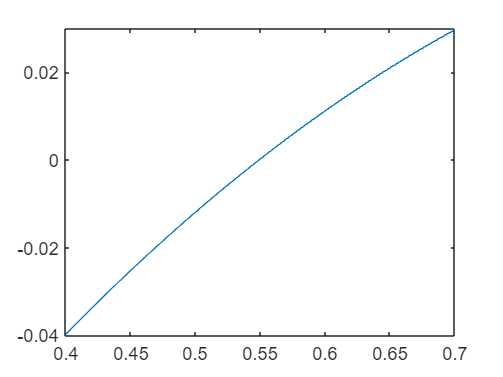

% Escriba su codigo ejecutable aca...
%fplot(f, x0) parece que el rango debe ser vectorizado
% x0_vectorizado = linspace(0.4, 0.7, 1000) % función tomada de MATLAB answers.
%fplot(f) % función tomada de MATLAB answers.

fplot(f, [0.4 0.7])

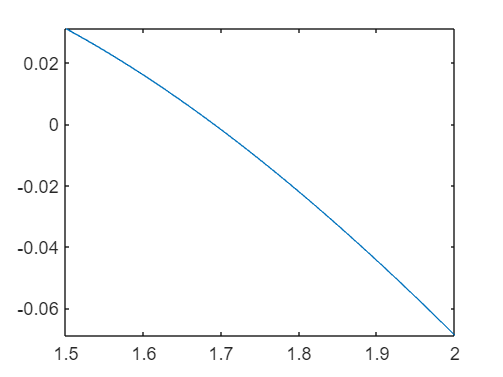


fplot(f, [1.5, 2])

c) Utilice al menos dos metodos (biseccion, punto fijo, Newton-Rhapson, Secante, ...) para aproximar numericamente las soluciones del inciso a). Para ello escriba esos metodos como M-funciones al final de este documento para utilizarlos en los codigos ejecutables. Ademas debe presentar tablas como las que se vieron en clases. 

% Escriba su codigo ejecutable aca...

% Estos metodos los subi a github el dia que los hicimos en clase, en caso
% de que se requiera evidencia. https://github.com/JosefRuzicka/Numerical-Methods


% metodo de biseccion, utilizamos el intervalo del ejercicio y la
% tolerancia tomada de la clase.
a=0.4; b=0.7; tol=1e-2

tol = 0.0100

[c, iters, table] = biseccionT(f, a, b, tol)

c = 0.5453

iters = 5

table = 6×5 table
    k       a          c        b         f(c)    
    _    _______    _______    ____    ___________

    0        0.4       0.55     0.7     0.00023202
    1        0.4      0.475    0.55      -0.018427
    2      0.475     0.5125    0.55     -0.0087661
    3     0.5125    0.53125    0.55     -0.0041846
    4    0.53125    0.54063    0.55     -0.0019557
    5    0.54063    0.54531    0.55    -0.00085672



% x0 e itermax tomadas de la clase para el metodo de punto fijo.
x0=1 ;iterMax=10;
[x, k, T] = fixed_point_table(f, x0, tol, iterMax)

x = -0.5178

k = 10

T = 11×4 table
    k        x          f(x)       error  
    __    ________    ________    ________

     0           1    0.059035     0.94097
     1    0.059035    -0.17135      15.939
     2    -0.17135    -0.29301      1.3445
     3    -0.29301     -0.3679     0.41519
     4     -0.3679     -0.4176     0.20355
     5     -0.4176     -0.4521     0.11903
     6     -0.4521    -0.47673    0.076298
     7    -0.47673    -0.49467    0.051671
     8    -0.49467    -0.50791    0.036262
     9    -0.50791    -0.51778    0.026072
    10    -0.51778     -0.5252    0.019068


% Ejemplo, esto no es parte de la tarea
% Escriba su codigo ejecutable aca...

%[a, b] = funcEjemplo([3,2])

### **Funciones (no ponga codigo ejecutable aca)**

function [bool] = PuntoEnTriangulo(X,Y,Z,P)
% X, Y, Z y P son puntos en un espacio bidimensional, por lo tanto
% presentan la forma X = [x, y] donde 'x' y 'y' son coordenadas en el espacio.
    
    bool = false;
    total_puntos = 4; %por si quisieramos usar más puntos a futuro
    puntos = [X; Y; Z; P];
    areas = [];

    % Queremos obtener todas las combinaciones de puntos para calcular su
    % area, no importa en el órden de las areas porque lo que queremos
    % hacer es sumarlas, aunque sabemos que la primer posición contendra el
    % area del triangulo XYZ
    for i = 1:total_puntos-2
        for j = i+1:total_puntos-1
            for k = i+2:total_puntos
                x_coords = [puntos(i,1) puntos(j,1) puntos(k,1)];
                y_coords = [puntos(i,2) puntos(j,2) puntos(k,2)];
                areas(end+1) = polyarea(x_coords, y_coords);
            end
        end
    end

    areas
    % La versión 'quemada' se vería así
    %x_coords = [X(1), Y(1), Z(1)]
    %y_coords = [X(2), Y(2), Z(2)]  
    %A = polyarea(x_coords, y_coords)

    %x_coords = [X(1), Y(1), P(1)]
    %y_coords = [X(2), Y(2), P(2)]  
    %A1 = polyarea(x_coords, y_coords)...

    % Ahora verificamos si se cumple la condición
    % usamos la operacion de suma de valores de vector, y un slice para no
    % sumar el valor del area A = XYZ
    if areas(1) == sum((areas(2:end)))
        bool = true;
    end

end

% Biseccion
function [c, iters, T] = biseccionT(f, a, b, tol)

    if f ( a ) * f ( b ) > 0
        disp ( ' No se cumple el cambio de signo ')
        return
    end

    T(1,:) = zeros(1,5);
    
    iters = floor ( log2 (( b - a ) / tol ) ) + 1;
    
    for k = 1:iters
        c = (a+b)/2;
        T(k,:) = [k-1, a, c, b, f(c)];

        if f(c) == 0
            a = c;
            b = c;
        elseif f(a)*f(c) < 0
            b = c;
        else
            a = c;
        end
    end

    c = (a+b)/2;
    T(iters+1,:) = [iters, a, c, b, f(c)];

    T = array2table(T, 'VariableNames', {'k', 'a', 'c', 'b', 'f(c)'});
end

%Punto fijo
function [x, k, T] = fixed_point_table(f, x0, tol, iterMax)
    k = 0;
    x = x0;
    err = tol+1;
    t(1,:) = [k x f(x) abs(x-f(x))];
    while (k < iterMax) && (err > tol)
        x = f(x);
        err = abs(x-x0)/abs(x);
        x0 = x;
        k = k+1;
        t(k+1,:) = [k x f(x) err];
    end
    T = array2table(t, 'VariableNames', {'k', 'x', 'f(x)', 'error'});
end

function [y, z] = funcEjemplo(x)
% Esta funcion es un ejemplo
y = x(1)^2 + 2*x(2);
z = -x(1)*x(2);
end
